n = 50;
min_val = 100;
max_val = 200;

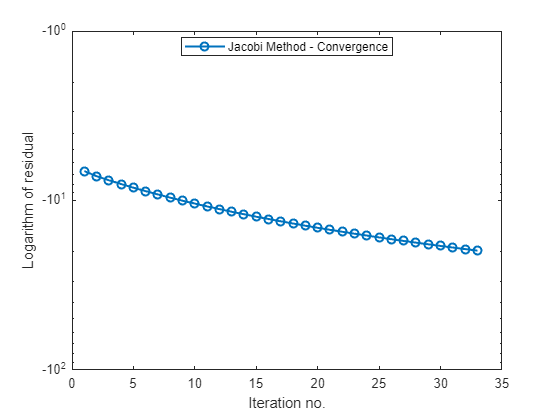

[A_d, b_d] = gen_mat(n, 1.0, min_val, max_val);
[A_s, b_s] = gen_mat(n, 0.5, min_val, max_val);

tic;
[val_jac_d, iter_jac_d] = my_jacobi(A_d, b_d);

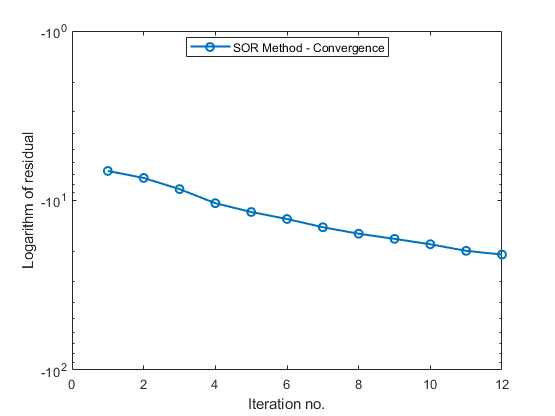

jac_dense = toc;

omega = find_omega(A_d);
tic;
[val_SOR_d, iter_SOR_d] = my_SOR(A_d, b_d, omega);

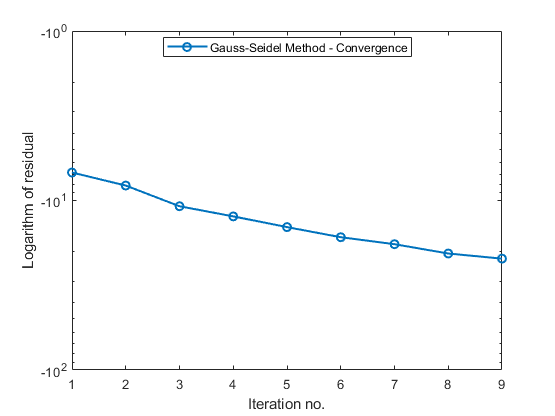

sor_dense = toc;

tic;
[val_gauss_d, iter_gauss_d] = my_gauss_seidel(A_d, b_d);

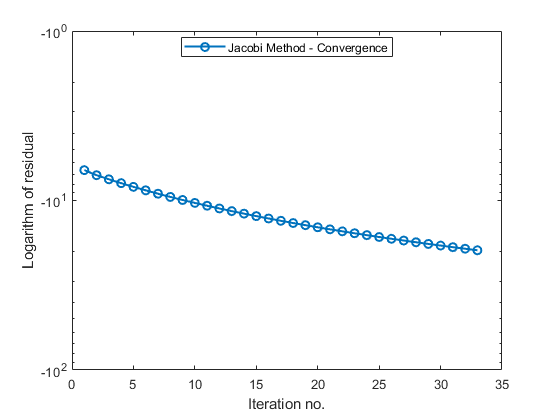

gauss_dense = toc;

tic;
[val_jac_s, iter_jac_s] = my_jacobi(A_s, b_s);

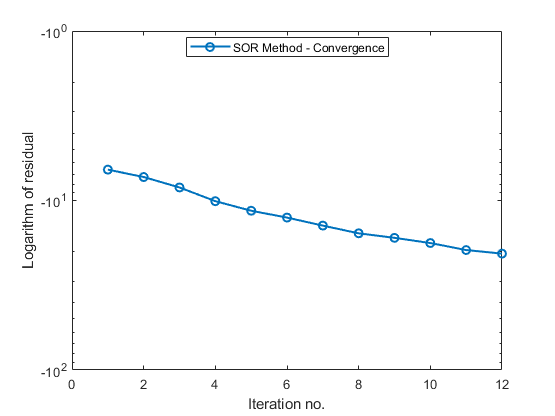

jac_sparse = toc;

omega = find_omega(A_s);
tic;
[val_SOR_s, iter_SOR_s] = my_SOR(A_s, b_s, omega);

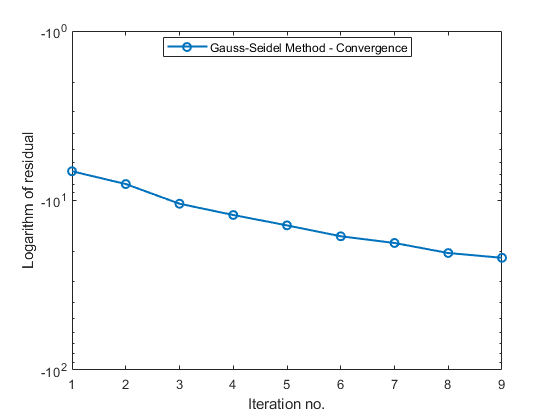

sor_sparse = toc;

tic;
[val_gauss_s, iter_gauss_s] = my_gauss_seidel(A_s, b_s);

gauss_sparse = toc;

fprintf("### TIMPI JACOBI:\n");

### TIMPI JACOBI:


fprintf("### JACOBI DENSE: %f | JACOBI SPARSE: %f\n\n", jac_dense, jac_sparse);

### JACOBI DENSE: 0.096090 | JACOBI SPARSE: 0.055178




fprintf("### TIMPI SOR:\n");

### TIMPI SOR:


fprintf("### SOR DENSE: %f | SOR SPARSE: %f\n\n", sor_dense, sor_sparse);

### SOR DENSE: 0.137501 | SOR SPARSE: 0.054939




fprintf("### TIMPI GAUSS-SEIDEL:\n");

### TIMPI GAUSS-SEIDEL:


fprintf("### GAUSS-SEIDEL DENSE: %f | GAUSS_SEIDEL SPARSE: %f\n\n", gauss_dense, gauss_sparse);

### GAUSS-SEIDEL DENSE: 0.067768 | GAUSS_SEIDEL SPARSE: 0.059976

